**Generate data using a simple RL model for a behavioral task with .9:.1 reward probabilities and one reversal**

addpath('helper functions')
addpath('metric functions')
trial_cnt = 200;
alpha = .25;
beta = 5;
reward_prob = [ones(trial_cnt/2, 2).*[.1, .9]; ones(trial_cnt/2, 2).*[.9, .1]];
[~,hr_side] = max(reward_prob, [], 2);
hr_side = hr_side';
[choice, reward, values] = simulate_simple_rl(reward_prob, alpha, beta);

strategy = choice(1:end-1)==choice(2:end);
option = choice == hr_side;

**Visualize simulated data**

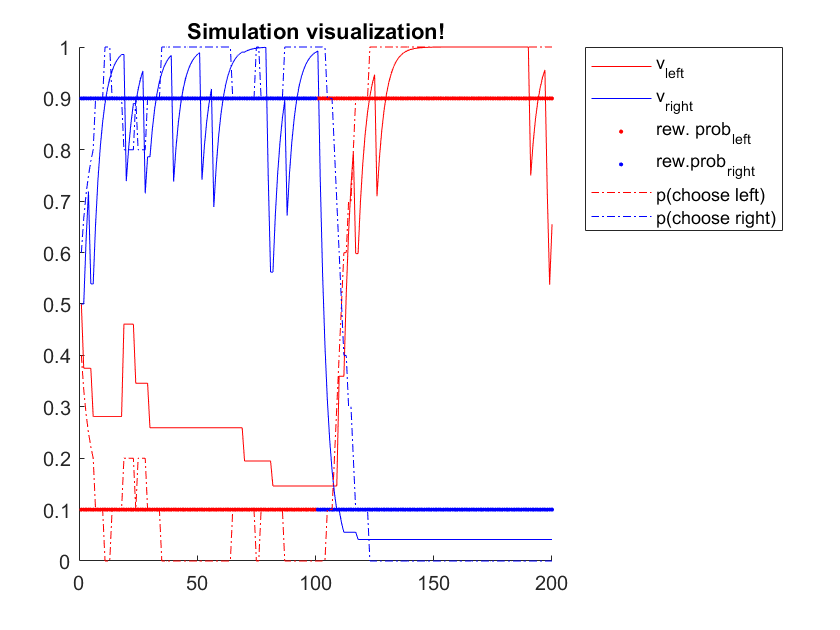

figure; hold on;
title("Simulation visualization!")
plot(values(:, 1), 'r-'); hold on;
plot(values(:, 2), 'b-');
plot(reward_prob(:, 1), 'r.');
plot(reward_prob(:, 2), 'b.');
plot(movmean(choice==1,10), 'r-.');
plot(movmean(choice==2, 10), 'b-.');
xlim([0, trial_cnt]);
legend(["v_{left}", "v_{right}", "rew. prob_{left}", "rew.prob_{right}", "p(choose left)", "p(choose right)"], 'location', 'bestoutside');

**Use formulas to calculate entropy metrics**


choice = (choice-1)*2-1; % choice must be encoded as -1 = opt 1, 1 =opt 2 for the way fxns are currently written
hr_side = (hr_side-1)*2-1; % same for hr_side
metric_output = entropy_metrics(choice', reward', hr_side'); % inputs must be column arrays


**Print each entropy metric**

fields = fieldnames(metric_output);
for i=1:length(fields)
    disp(fields{i} + ": " + metric_output.(fields{i}));
end

ERDS_lose: 0.15
ERDS_win: 0.18766
ERDS: 0.33766
EODS_worse: 0.089645
EODS_better: 0.2376
EODS: 0.32724
ERODS_loseworse: 0.085214
ERODS_losebetter: 0.052735
ERODS_winworse: 0
ERODS_winbetter: 0.16288
ERODS: 0.30083
